# Testing all RTB functions

Read section 2.4 of Peter Corke Book

**Skip 'Twist'  which we will not use in this course**

## **RTB functions. Summary tables**

### **2D**

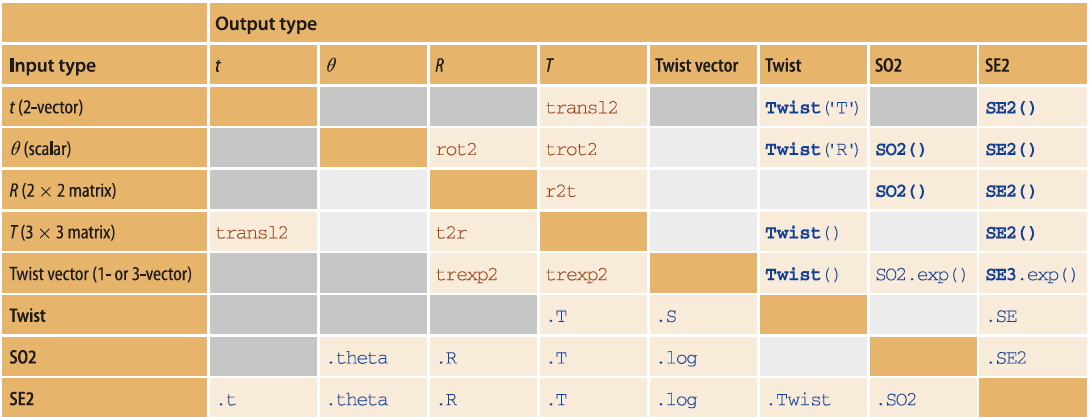

### 3D

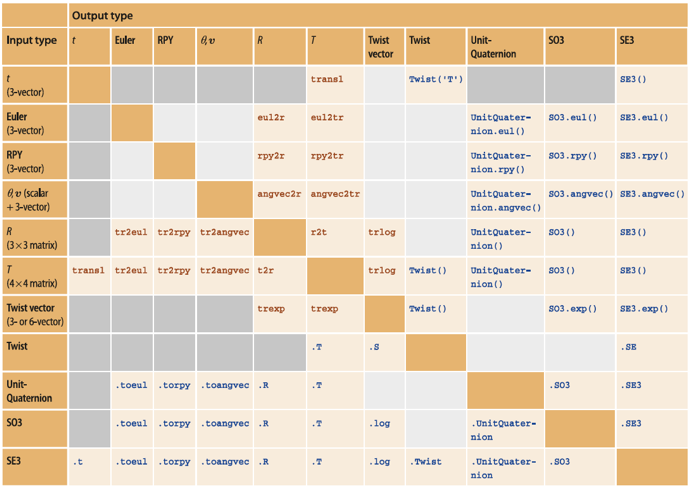

## RTB equivalence for Matrix(Classic) / Class-Object (New)

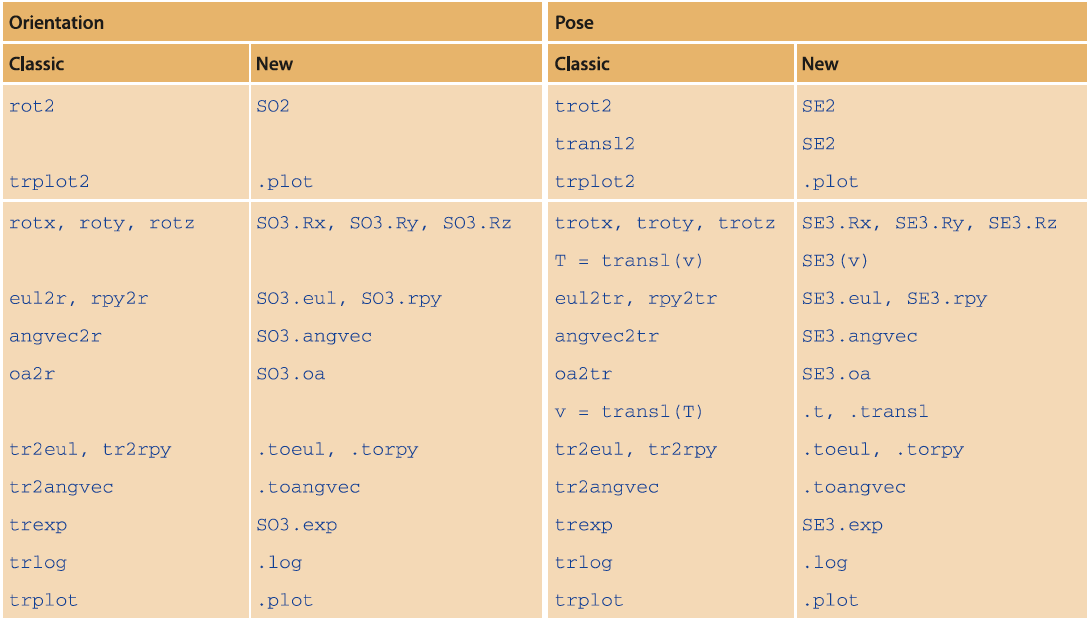

From here on we will use a mixture of classic functions and the newer classes.

clear
close all

## Input a vector

p=[1 2 3]'

p =      1
     2
     3


### Get T 

T=transl(p)

T =      1     0     0     1
     0     1     0     2
     0     0     1     3
     0     0     0     1


### Get a SE3

P=SE3(p) % P is a object

 

P = 
         1         0         0         1
         0         1         0         2
         0         0         1         3
         0         0         0         1


P1=[P.t] % P1 recover the point as a vector

P1 =      1
     2
     3


P11=P.t

P11 =      1
     2
     3


p=[1 2 3;4 5 6; 7 8 9] 

p =      1     2     3
     4     5     6
     7     8     9


P=SE3(p) % is a 4x4. Note the row(1) -> x's; row(2) -> y's; row(3) -> z's ...

 

P(1) = 
         1         0         0         1
         0         1         0         2
         0         0         1         3
         0         0         0         1

P(2) = 
         1         0         0         4
         0         1         0         5
         0         0         1         6
         0         0         0         1

P(3) = 
         1         0         0         7
         0         1         0         8
         0         0         1         9
         0         0         0         1


ps=[P.t]

ps =      1     4     7
     2     5     8
     3     6     9


p=transl(P)

p =      1     2     3
     4     5     6
     7     8     9


## Input Euler Angles 

zyz=[0.1 0.2 0.3]

zyz =     0.1000    0.2000    0.3000


zyzs=[0.1 0.2 0.3;0.4 0.5 0.6;0.7 0.8 0.9; 0.5 0.6 0.8; 0.7 0.9 1]

zyzs =     0.1000    0.2000    0.3000
    0.4000    0.5000    0.6000
    0.7000    0.8000    0.9000
    0.5000    0.6000    0.8000
    0.7000    0.9000    1.0000


### Get R

R=rotz(zyz(1))*roty(zyz(2))*rotz(zyz(3))

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R1=eul2r(zyz)

R1 =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R2=eul2r(zyzs)

R2 = R2(:,:,1) =

    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R2(:,:,2) =

    0.4472   -0.7778    0.4416
    0.8021    0.5672    0.1867
   -0.3957    0.2707    0.8776


R2(:,:,3) =

   -0.1734   -0.8179    0.5487
    0.8781    0.1239    0.4621
   -0.4459    0.5619    0.6967


R2(:,:,4) =

    0.1607   -0.8536    0.4955
    0.9052    0.3276    0.2707
   -0.3934    0.4050    0.8253


R2(:,:,5) =

   -0.2852   -0.7481    0.5991
    0.8600    0.0763    0.5046
   -0.4232    0.6591    0.6216


### Get T

R3=eul2tr(zyz)

R3 =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


R4=eul2tr(zyzs)

R4 = R4(:,:,1) =

    0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


R4(:,:,2) =

    0.4472   -0.7778    0.4416         0
    0.8021    0.5672    0.1867         0
   -0.3957    0.2707    0.8776         0
         0         0         0    1.0000


R4(:,:,3) =

   -0.1734   -0.8179    0.5487         0
    0.8781    0.1239    0.4621         0
   -0.4459    0.5619    0.6967         0
         0         0         0    1.0000


R4(:,:,4) =

    0.1607   -0.8536    0.4955         0
    0.9052    0.3276    0.2707         0
   -0.3934    0.4050    0.8253         0
         0         0         0    1.0000


R4(:,:,5) =

   -0.2852   -0.7481    0.5991         0
    0.8600    0.0763    0.5046         0
   -0.4232    0.6591    0.6216         0
         0         0         0    1.0000


### Get a Quaternion

Q=UnitQuaternion.eul(zyz)

 
Q = 
 
0.97517 < 0.0099667, 0.099335, 0.19768 >
 


Q.v

ans =     0.0100    0.0993    0.1977


Q.s

ans = 0.9752

### Get a SO3

T=SO3.eul(zyz)

 

T = 
    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


T=SO3.eul(zyzs)

 

T(1) = 
    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801

T(2) = 
    0.4472   -0.7778    0.4416
    0.8021    0.5672    0.1867
   -0.3957    0.2707    0.8776

T(3) = 
   -0.1734   -0.8179    0.5487
    0.8781    0.1239    0.4621
   -0.4459    0.5619    0.6967

T(4) = 
    0.1607   -0.8536    0.4955
    0.9052    0.3276    0.2707
   -0.3934    0.4050    0.8253

T(5) = 
   -0.2852   -0.7481    0.5991
    0.8600    0.0763    0.5046
   -0.4232    0.6591    0.6216


### Get a SE3

T=SE3.eul(zyz)

 

T = 
    0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0         1


T=SE3.eul(zyzs)

 

T(1) = 
    0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0         1

T(2) = 
    0.4472   -0.7778    0.4416         0
    0.8021    0.5672    0.1867         0
   -0.3957    0.2707    0.8776         0
         0         0         0         1

T(3) = 
   -0.1734   -0.8179    0.5487         0
    0.8781    0.1239    0.4621         0
   -0.4459    0.5619    0.6967         0
         0         0         0         1

T(4) = 
    0.1607   -0.8536    0.4955         0
    0.9052    0.3276    0.2707         0
   -0.3934    0.4050    0.8253         0
         0         0         0         1

T(5) = 
   -0.2852   -0.7481    0.5991         0
    0.8600    0.0763    0.5046         0
   -0.4232    0.6591    0.6216         0
         0         0         0         1


## Input RPY

The same as for Euler angles apply for RPY

## Input R

### Get Euler

euler = tr2eul(R1)

euler =     0.1000    0.2000    0.3000


### Get RPY

rpy = tr2rpy(R3)

rpy =     0.0598    0.1910    0.4057


Get Angles

angvec = tr2angvec(R3)

angvec = 0.4466

Get T

%T = r2t(R3)

Get Twist Vector

twist = trlog(R3)

twist =          0   -0.3987    0.2003         0
    0.3987         0   -0.0201         0
   -0.2003    0.0201         0         0
         0         0         0         0


Get Unit Quaternion

uq = UnitQuaternion(R3)

 
uq = 
 
0.97517 < 0.0099667, 0.099335, 0.19768 >
 


Get SO3

so3 = SO3(R3)

 

so3 = 
    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


GetSE3

se3 = SE3(R3)

 

se3 = 
    0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0         1


## Having RPY

Get R

R = rpy2r(rpy)

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


Get T

R = rpy2tr(rpy)

R =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


Get Unit Quaternion

uq = UnitQuaternion.rpy(rpy)

 
uq = 
 
0.97517 < 0.0099667, 0.099335, 0.19768 >
 


Get SO3

so3 = SO3.rpy(rpy)

 

so3 = 
    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


Get SE3

se3 = SE3.rpy(rpy)

 

se3 = 
    0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0         1


## Having AngVec

Get R

R = angvec2r(angvec, zyz)

R =     0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get T

T = angvec2tr(angvec, zyz)

T =     0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0    1.0000


Get Unit Quaternion 

uq = UnitQuaternion.angvec(angvec, zyz)

 
uq = 
 
0.97517 < 0.059187, 0.11837, 0.17756 >
 


Get SO3

so3 = SO3.angvec(angvec, zyz)

 

so3 = 
    0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get SE3

se3 = SE3.angvec(angvec, zyz)

 

se3 = 
    0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0         1


## Having T

Get t

t = transl(T)

t =      0
     0
     0


Get Euler

euler = tr2eul(T)

euler =    -0.2835    0.2655    0.6438


Get RPY

rpy = tr2rpy(T)

rpy =     0.1618    0.2114    0.3774


Get AngVec

angvec = tr2angvec(T)

angvec = 0.4466

Get R

R = t2r(T)

R =     0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get Twist Vector

twist = trlog(T)

twist =          0   -0.3581    0.2387         0
    0.3581         0   -0.1194         0
   -0.2387    0.1194         0         0
         0         0         0         0


Get Unit Quaternion

uq = UnitQuaternion(T)

 
uq = 
 
0.97517 < 0.059187, 0.11837, 0.17756 >
 


Get SO3

so3 = SO3(T)

 

so3 = 
    0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get SE3

se3 = SE3(T)

 

se3 = 
    0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0         1


## Having Twist Vector

Get R

R = trexp(twist)

R =     0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0    1.0000


Get T

T = trexp(twist)

T =     0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0    1.0000


Get SO3

so3 = SO3.exp(twist)

 

so3 = 
    0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get SE3

se3 = SE3.exp(twist)

 

se3 = 
    0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0         1


## Having Unit Quaternion

Get Euler

euler = uq.toeul

euler =    -0.2835    0.2655    0.6438


Get RPY

rpy = uq.torpy

rpy =     0.1618    0.2114    0.3774


Get AngVec

angvec = uq.toangvec

angvec = 0.4466

Get R

R = uq.R

R =     0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get T

T = uq.T

T =     0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0    1.0000


Get SO3

so3 = uq.SO3

 

so3 = 
    0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get SE3

se3 = uq.SE3

 

se3 = 
    0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0         1


## Having SO3

Get Euler

euler = so3.toeul

euler =    -0.2835    0.2655    0.6438


Get RPY

rpy = so3.torpy

rpy =     0.1618    0.2114    0.3774


Get AngVec

angvec = so3.toangvec

angvec = 0.4466

Get R

R = so3.R

R =     0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get T

T = so3.T

T =     0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0    1.0000


Get Twist Vector

twist = so3.log

twist =          0   -0.3581    0.2387
    0.3581         0   -0.1194
   -0.2387    0.1194         0


Get Unit Quaternion

uq = so3.UnitQuaternion

 
uq = 
 
0.97517 < 0.059187, 0.11837, 0.17756 >
 


Get SE3

se3 = so3.SE3

 

se3 = 
    0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0         1


## Having SE3

Get t

t = se3.t

t =      0
     0
     0


Get Euler

euler = se3.toeul

euler =    -0.2835    0.2655    0.6438


Get RPY

rpy = se3.torpy

rpy =     0.1618    0.2114    0.3774


Get AngVec

angvec = se3.toangvec

angvec = 0.4466

Get R

R = se3.R

R =     0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650


Get T

T = se3.T

T =     0.9089   -0.3323    0.2519         0
    0.3603    0.9299   -0.0734         0
   -0.2098    0.1575    0.9650         0
         0         0         0    1.0000


Get Twist vector

twist = se3.log

twist =          0   -0.3581    0.2387         0
    0.3581         0   -0.1194         0
   -0.2387    0.1194         0         0
         0         0         0         0


Get Unit Quaternion

uq = se3.UnitQuaternion

 
uq = 
 
0.97517 < 0.059187, 0.11837, 0.17756 >
 


Get SO3

so3 = se3.SO3

 

so3 = 
    0.9089   -0.3323    0.2519
    0.3603    0.9299   -0.0734
   -0.2098    0.1575    0.9650
